clear;clc;close all;

n = 20;
boundary1 = 300;
boundary2 = 400;
    
    
X = solver(n,boundary1,boundary2);

A =    -8.0500    4.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.0000   -8.0500    4.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    4.0000   -8.0500    4.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    4.0000   -8.0500    4.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0    4.0000   -8.0500    4.0000         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0 

B =        -1210
         -10
         -10
         -10
         -10
         -10
         -10
         -10
         -10
         -10


X =   294.0161
  289.2074
  285.5138
  282.8891
  281.3005
  280.7281
  281.1649
  282.6162
  285.1003
  288.6481


deltaX = 10/n

deltaX = 0.5000

length = (10/deltaX - 1)

length = 19


yaxis = ones(1,length+2);
yaxis(1) = boundary1;
yaxis(length+2) = boundary2;

yaxis(2:length+1) = X 

yaxis =   300.0000  294.0161  289.2074  285.5138  282.8891  281.3005  280.7281  281.1649  282.6162  285.1003  288.6481  293.3040  299.1261  306.1874  314.5760  324.3968  335.7726  348.8455  363.7790  380.7598  400.0000



xaxis = 0:deltaX:10

xaxis =          0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000    5.5000    6.0000    6.5000    7.0000    7.5000    8.0000    8.5000    9.0000    9.5000   10.0000


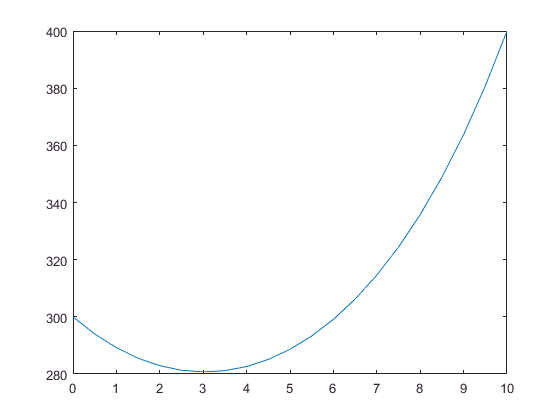


figure
plot(xaxis, yaxis)

function [X,length] = solver(n,boundary1,boundary2)
    deltaX = 10/n;
    xvalue = 0:deltaX:10;
    
    length = (10/deltaX) - 1;
    
    startvalue = -10-(boundary1/(deltaX^2));
    endvalue = -10-(boundary2/(deltaX^2));
    
    coeff1 = 1/(deltaX^2);
    coeff2 = -(2/(deltaX^2) + 0.05);
    coeff3 = 1/(deltaX^2);
    
    vneg1 = coeff1*ones(1,length-1);
    vzero = coeff2*ones(1,length);
    vpos1 = coeff3*ones(1,length-1);
    
    A = diag(vneg1,-1) + diag(vzero,0) + diag(vpos1,1)
    
    B = -10*(ones(length, 1));
    B(1) = startvalue;
    B(length) = endvalue;
    B
    
    X = A\B
    
end  